clear 
clc

a) Displaying the initial system

%given data
K=1;
tau=1/25;
D=0;
Kv=100;
ess=1/Kv;
%transfer funtion
s=tf('s');
%open loop system
%Gp = K/(s*(tau*s+1));
num=K;
den=[tau,1,0];
Gp=tf(num,den)

Gp =
 
       1
  ------------
  0.04 s^2 + s
 
Continuous-time transfer function.



The initial system has 2 poles at p1=0 and p2=-25

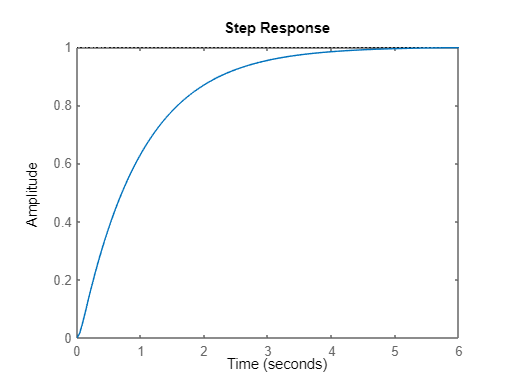

%closed loop system
Gp_closed=feedback(Gp,1);
%plotting closed_loop step
figure()
step(Gp_closed)

%displaying step info
stepinfo(Gp_closed)

ans = struct with fields:
         RiseTime: 2.1071
    TransientTime: 3.7915
     SettlingTime: 3.7915
      SettlingMin: 0.9002
      SettlingMax: 0.9993
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9993
         PeakTime: 7.0166


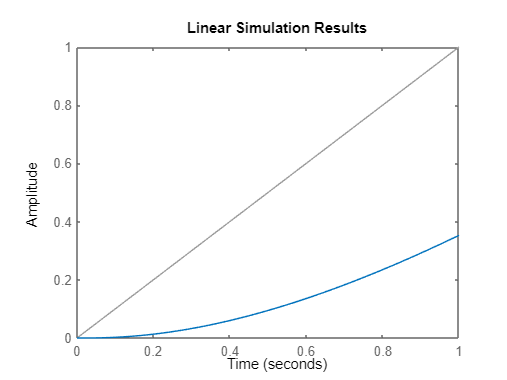

%linear simulation of the original system
t = 0:0.01:1;
figure()
lsim(Gp_closed,t,t)

As seen on the plot above the response of the system significantly lags behind the expected ramp of the step response. We will now design a lead-lag compensator using Matlab's sisotool to fix it.

b) Designing an initial lead-lag compensator using sisotool

%controlSystemDesigner(compensator1.mat);

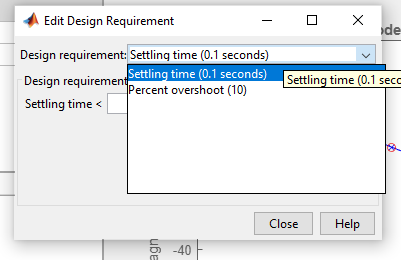

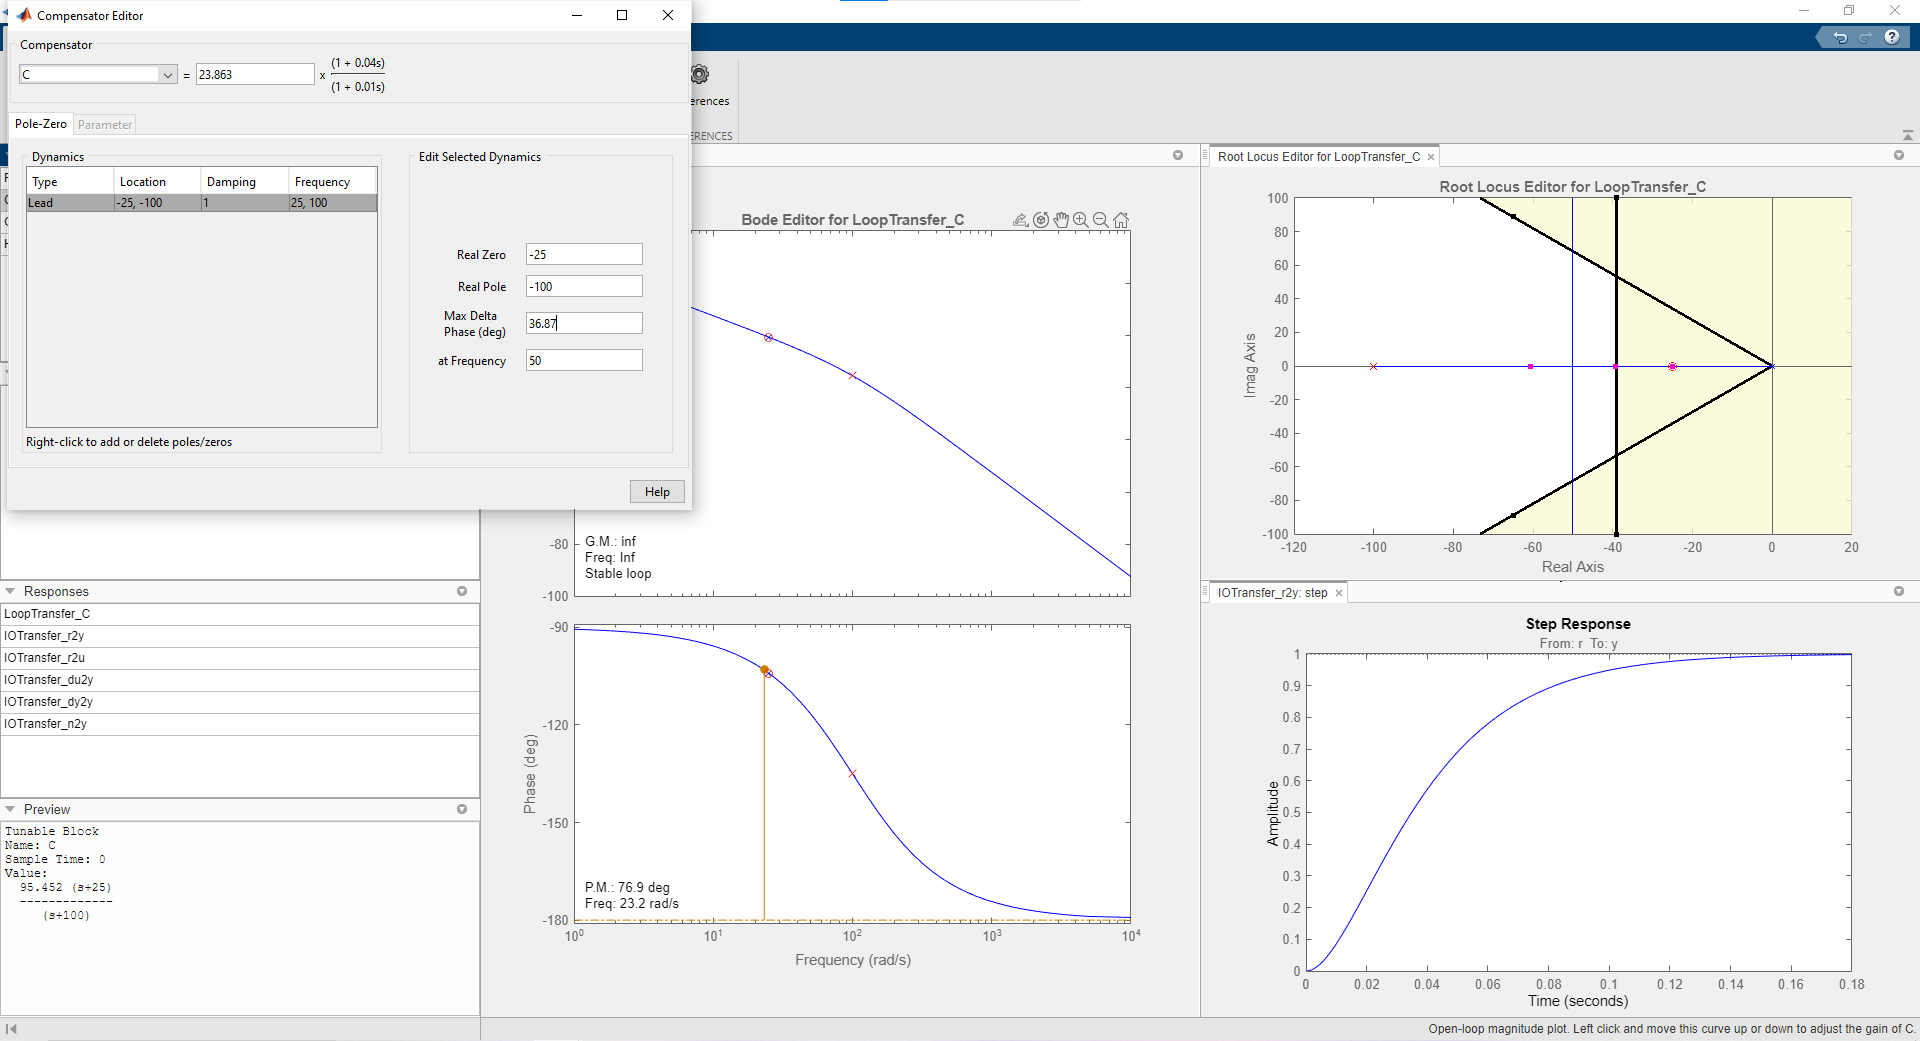

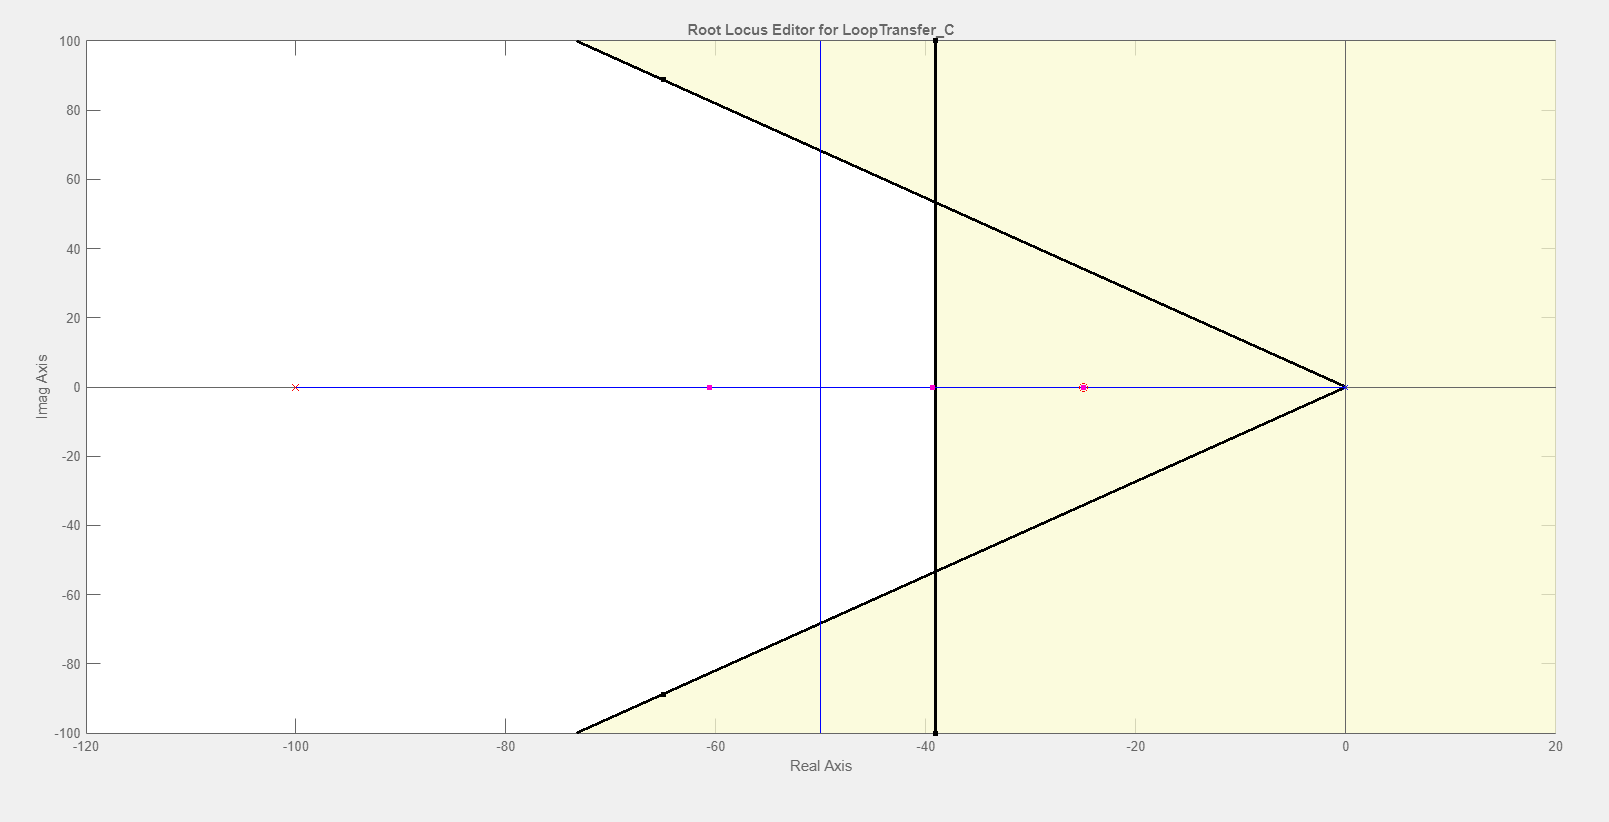

Based on the results obtained we can now test our compensator, and see if it fits all the requirements.

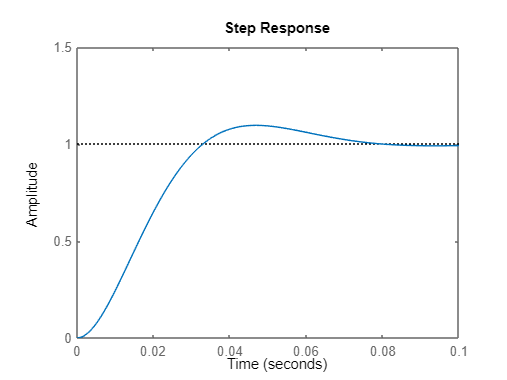

%compensator equation
Gc = (2.8*s + 70)/(0.01*s + 1);
%creating a closed loop compensated system
Gp_closed_comp = feedback(Gc*Gp,1);
%plotting results
figure();
step(Gp_closed_comp); ylim([0 1.5]);

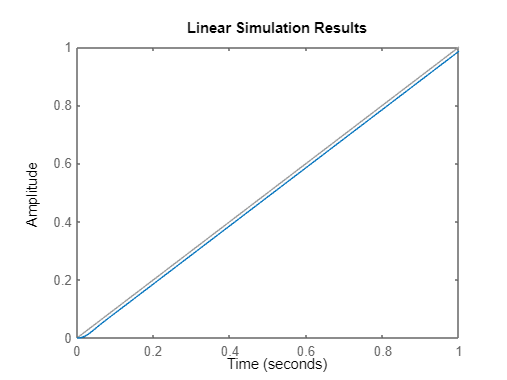

figure();
lsim(Gp_closed_comp,t,t);

%checking if the results fit the requirements:
stepinfo(Gp_closed_comp)

ans = struct with fields:
         RiseTime: 0.0221
    TransientTime: 0.0710
     SettlingTime: 0.0710
      SettlingMin: 0.9127
      SettlingMax: 1.0962
        Overshoot: 9.6167
       Undershoot: 0
             Peak: 1.0962
         PeakTime: 0.0470


Both percentage overshoot (9.617%<10%) & settling time (0.0710<0.01) are within the design requirements , but Steady state error (0.014>0.01) is still too big. We can fix this by adjusting values of Kc and position of the pole p.

%controlSystemDesigner(compensator2.mat);

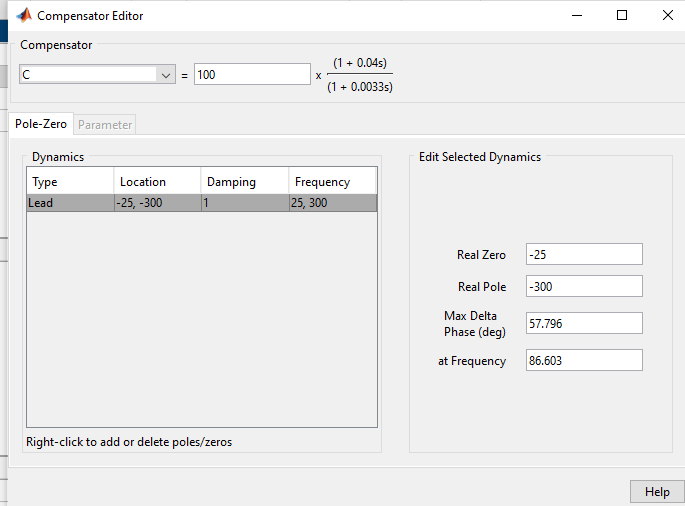

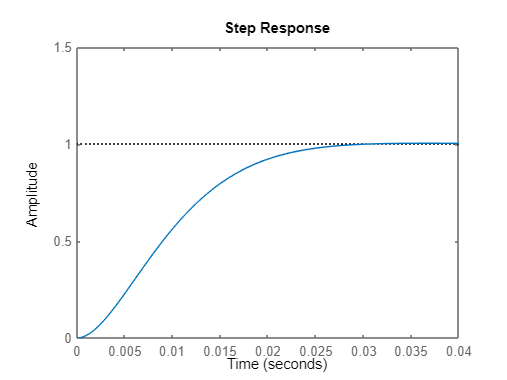

%checking results
%compensator equation
Gc_new = (4*s + 100)/(0.0033*s + 1);
%creating a closed loop compensated system
Gp_closed_comp_new = feedback(Gc_new*Gp,1);
%plotting results
figure();
step(Gp_closed_comp_new); ylim([0 1.5]);

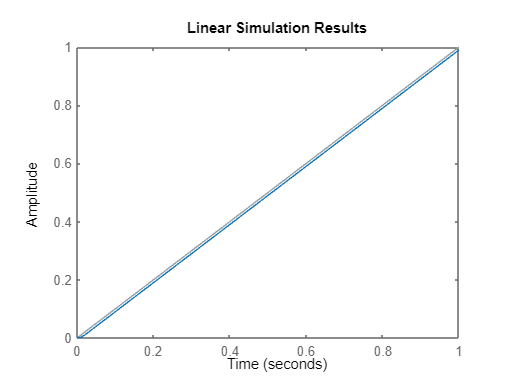

figure();
lsim(Gp_closed_comp_new,t,t);

%checking if the results fit the requirements:
stepinfo(Gp_closed_comp_new)

ans = struct with fields:
         RiseTime: 0.0158
    TransientTime: 0.0252
     SettlingTime: 0.0252
      SettlingMin: 0.9009
      SettlingMax: 1.0039
        Overshoot: 0.3873
       Undershoot: 0
             Peak: 1.0039
         PeakTime: 0.0368


This time, all the design requirements were met. Percentage overshoot (0.387%<10%), settling time (0.0025<0.01) and steady state error (0.01=0.01) are within the design requirements.

c) Adjusting gain K1 to 2, and checking the influence on the compensated system:

%creating new plant with gain K1=2
K1_new = 2;
num2=K1_new;
Gp2=tf(num2,den)

Gp2 =
 
       2
  ------------
  0.04 s^2 + s
 
Continuous-time transfer function.



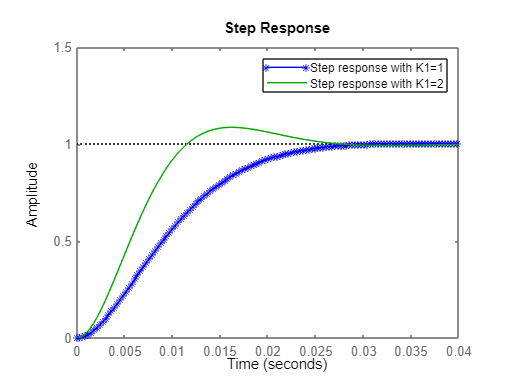

%creating closed-loop system
Gp_closed_comp_new2 = feedback(Gc_new*Gp2,1);
%comparing step responses of both systems
figure();
step(Gp_closed_comp_new, 'b*-'); ylim([0 1.5]); hold on;
step(Gp_closed_comp_new2, 'g');
legend('Step response with K1=1', 'Step response with K1=2')

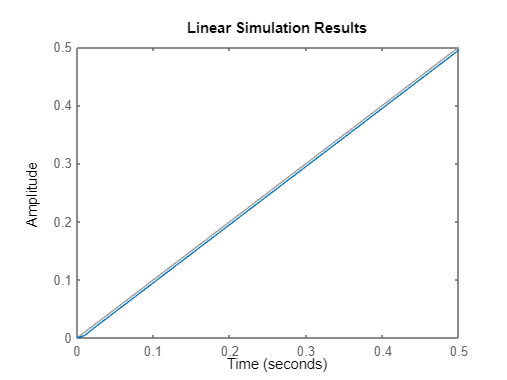

%checking linear simulation for the new system
figure();
t = 0:0.01:0.5;
lsim(Gp_closed_comp_new2,t,t);

%collecting required data for comparaison
S1=stepinfo(Gp_closed_comp_new);
S2=stepinfo(Gp_closed_comp_new2);

res=zeros(2,3);

res(1,1)=S1.Overshoot;
res(1,2)=S1.SettlingTime;
res(1,3)=0.01;

res(2,1)=S1.Overshoot;
res(2,2)=S1.SettlingTime;
res(2,3)=0.005;
%1st row syst with gain K1=1, 2nd row K1=2. 
% Order of values: overshoot, settlign time, steady state error
res

    From the results presented above we can observe that both systems performance is quite good and in both cases it meets the initial requirements. The value of the steady state error, for the system with K1=2 , is lower than for the system with K1=1 . It occurs due to increas in the gain.On the other hand an increase in gain results also in an increase of percent overshoot. The value of settling time is similar although a bit better for higher gain. These results show that the improved lead-lag compensator is robust to the change in the gain K1.

    We can say that our system is robust beacouse it is a closed-loop system, and therefore it is less sensitive to variations of the component. By closing the loop on the system it continuously calculates expected values to determine how much they should be increased/decreased to achieve its desired values. Thanks to this feedback our system is able to reject possible disturbances.

d) Design of a robust compensator under system disturbances:

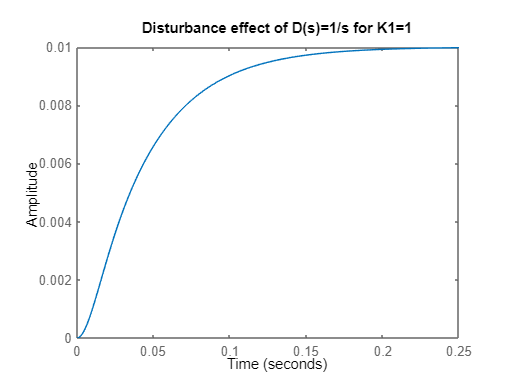

%disturbance, if D(s)=1/s, then D(t)=1
D=1;
%disturbed system
effect = Gp/(D+Gp*Gc_new);
%plotting step of the disturbed system
figure();
step(effect); xlim([0 0.25]);
title('Disturbance effect of D(s)=1/s for K1=1');

Response of the system is 100x smaller.